# Lasso and Elastic Net Regularization

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and plots the data.

data = readtable("data\dataRidge.xlsx", Sheet="data");
XTrain = readtable("data\dataRidge.xlsx", Sheet="XTrain");
XTest = readtable("data\dataRidge.xlsx", Sheet="XTest");
yTrain = readtable("data\dataRidge.xlsx", Sheet="yTrain");
yTest = readtable("data\dataRidge.xlsx", Sheet="yTest");
whos data XTrain XTest yTrain yTest

  Name          Size            Bytes  Class    Attributes

  XTest        60x2              2151  table              
  XTrain      140x2              3431  table              
  data        200x3              6201  table              
  yTest        60x1              1457  table              
  yTrain      140x1              2097  table              



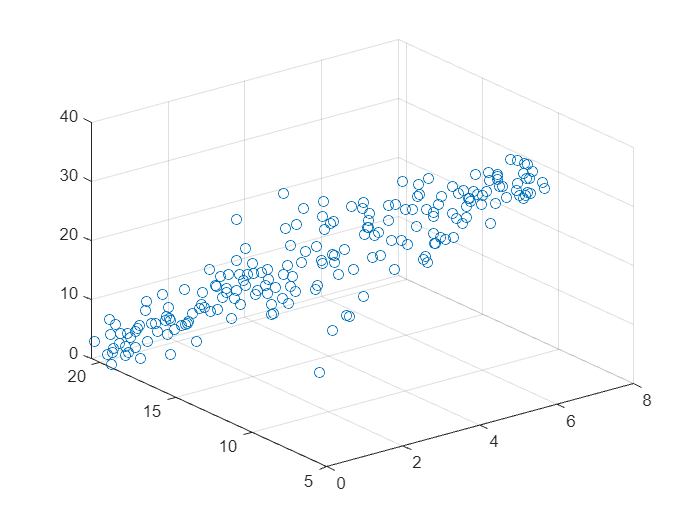

scatter3(data.X1, data.X2, data.Y)

## Tasks 1 & 3

Training data is saved in `XTrain` and `yTrain`.

You can use the `lasso` function to perform lasso regression.

`lambda` `=` `(``0``:``10``)``/``length``(``y``)``;`

`[``coef``,``fitInfo``]` `=` `lasso``(``X``,``y``,``"Lambda"``,``lambda``)``;`

Note that `lasso` uses a different scaling for `lambda`. Scale `lambda` by the number of observations to have the same interpretation as for `ridge`.

Notice that once the coefficient of X2 reaches zero, it remains zero, which means the algorithm has identified X2 as a redundant predictor. You can use the MSE to evaluate its impact on the fit.

As with ridge regression, the predicted response is calculated by matrix multiplying the predictor matrix and the coefficient matrix. The intercept is stored in the `Intercept` field of the `fitInfo` structure.

`yp` `=` `fitInfo.Intercept` `+` `dataNew``*``coef`

lambda = (0:100) / length(yTrain.Y);
[b, fitInfo] = lasso(table2array(XTrain), yTrain.Y, "Lambda", lambda, "Alpha", 0.4);

Plot coefficients

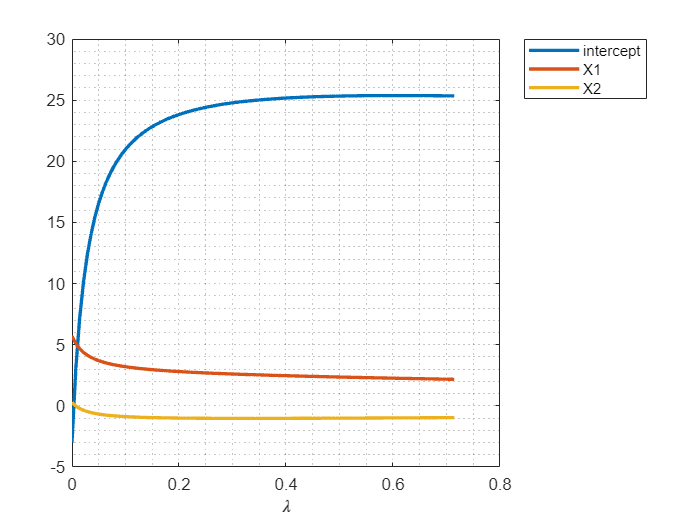

plot(lambda, [fitInfo.Intercept; b], "LineWidth", 2)
grid minor
legend("intercept", "X1", "X2")
xlabel("\lambda")

## Task 2

yPred = fitInfo.Intercept + table2array(XTest)*b;
mdlMSE = mean((yTest.Y - yPred).^2);
[minMSE, idx] = min(mdlMSE)

minMSE = 13.2367

idx = 18

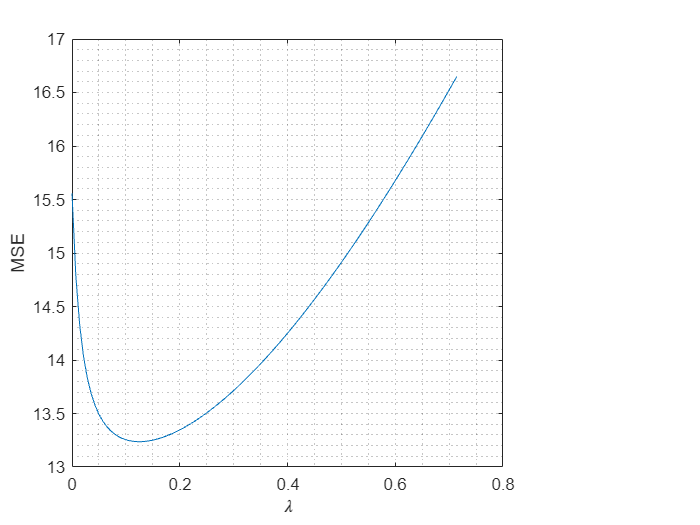


plot(lambda, mdlMSE)
grid minor
xlabel("\lambda")
ylabel("MSE")

Find coefficients corresponding to smallest MSE

b0 = fitInfo.Intercept(idx)

b0 = 21.9315

bX1 = b(1, idx)

bX1 = 3.0800

bX2 = b(2, idx)

bX2 = -0.9232